## Задание 5. Задача слежения для системы с астатизмом первого порядка (ПИ-регулятор)

## Постоянная скорость -  режим работы

simTimeStart = 0;
simTimeEnd = 10;
step = 0.01;
data.time=(simTimeStart:step:simTimeEnd)';
modelName = 'task5'; 

V = 2;
input = (V .* data.time);
data.signals(1).values = input;
data.signals(1).dimensions = 1;

### Испытание 1,2,3 - fixed kp

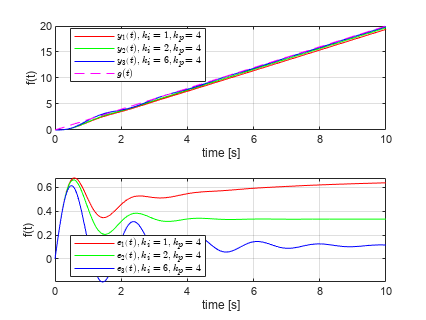

kp = 4;

load_system(modelName);
ki = 1;
out1 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
ki = 2;
out2 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
ki = 6;
out3 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out1.simout.Time;                
y_out1 = out1.simout.Data; y_out2 = out2.simout.Data; y_out3 = out3.simout.Data; 

figure;
subplot(2,1,1);
plot(time, y_out1, 'r');
hold on;
plot(time, y_out2, 'g');
hold on;
plot(time, y_out3, 'b');
hold on;
plot(time, V* time, 'magenta--');
title(' ');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('$y_1(t), k_i = 1, k_p = 4$','$y_2(t), k_i = 2, k_p = 4$','$y_3(t), k_i = 6, k_p = 4$','$g(t)$', 'Location', 'Best', 'Interpreter','latex');

subplot(2,1,2);
plot(time, V* time - y_out1, 'r');
hold on;
plot(time, V* time - y_out2, 'g');
hold on;
plot(time, V* time - y_out3, 'b');
hold on;
title(' ');      
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('$e_1(t), k_i = 1, k_p = 4$','$e_2(t), k_i = 2, k_p = 4$','$e_3(t), k_i = 6, k_p = 4$', 'Location', 'Best', 'Interpreter','latex');

save_file('output_task5_exp1')

### Испытание 4, 5, 6 - fixed ki

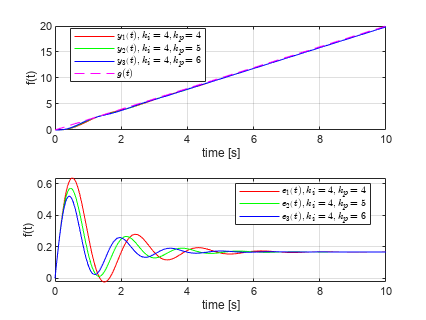

ki = 4;

load_system(modelName);
kp = 4;
out1 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
kp = 5;
out2 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
kp = 6;
out3 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out1.simout.Time;                
y_out1 = out1.simout.Data; y_out2 = out2.simout.Data; y_out3 = out3.simout.Data; 

figure;
subplot(2,1,1);
plot(time, y_out1, 'r');
hold on;
plot(time, y_out2, 'g');
hold on;
plot(time, y_out3, 'b');
hold on;
plot(time, V* time, 'magenta--');
title(' ');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('$y_1(t), k_i = 4, k_p = 4$','$y_2(t), k_i = 4, k_p = 5$','$y_3(t), k_i = 4, k_p = 6$','$g(t)$', 'Location', 'Best', 'Interpreter','latex');

subplot(2,1,2);
plot(time, V* time - y_out1, 'r');
hold on;
plot(time, V* time - y_out2, 'g');
hold on;
plot(time, V* time - y_out3, 'b');
hold on;
title(' ');      
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('$e_1(t), k_i = 4, k_p = 4$','$e_2(t), k_i = 4, k_p = 5$','$e_3(t), k_i = 4, k_p = 6$', 'Location', 'Best', 'Interpreter','latex');

save_file('output_task5_exp2')

### Испытание 7, 8, 9 - дополнительные

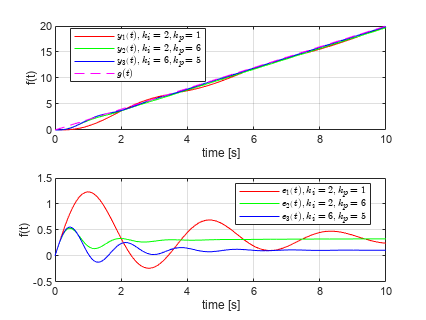

load_system(modelName);
ki = 2; kp = 1;
out1 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
ki = 2; kp = 6;
out2 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
ki = 6; kp = 5;
out3 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out1.simout.Time;                
y_out1 = out1.simout.Data; y_out2 = out2.simout.Data; y_out3 = out3.simout.Data; 

figure;
subplot(2,1,1);
plot(time, y_out1, 'r');
hold on;
plot(time, y_out2, 'g');
hold on;
plot(time, y_out3, 'b');
hold on;
plot(time, V* time, 'magenta--');
title(' ');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('$y_1(t), k_i = 2, k_p = 1$','$y_2(t), k_i = 2, k_p = 6$','$y_3(t), k_i = 6, k_p = 5$','$g(t)$', 'Location', 'Best', 'Interpreter','latex');

subplot(2,1,2);
plot(time, V* time - y_out1, 'r');
hold on;
plot(time, V* time - y_out2, 'g');
hold on;
plot(time, V* time - y_out3, 'b');
hold on;
title(' ');      
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('$e_1(t), k_i = 2, k_p = 1$','$e_2(t), k_i = 2, k_p = 6$','$e_3(t), k_i = 6, k_p = 5$', 'Location', 'Best', 'Interpreter','latex');

save_file('output_task5_exp3')

### Испытания - какие-то пять штук

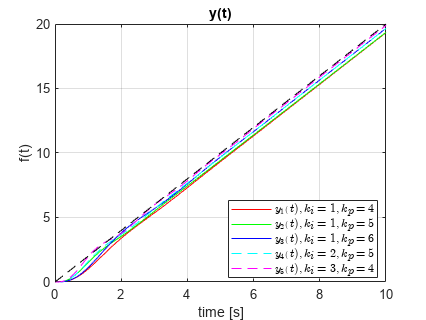

load_system(modelName);
ki = 1; kp = 2;
out1 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
ki = 1; kp = 4;
out2 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
ki = 2; kp = 2;
out3 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
ki = 2; kp = 4;
out4 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
ki = 6; kp = 5;
out5 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out1.simout.Time;                
y_out1 = out1.simout.Data; y_out2 = out2.simout.Data; y_out3 = out3.simout.Data; 
y_out4 = out4.simout.Data; y_out5 = out5.simout.Data; 

%%%    y(t)   %%%
figure;
plot(time, y_out1, 'r');
hold on;
plot(time, y_out2, 'g');
hold on;
plot(time, y_out3, 'b');
hold on;
plot(time, y_out4, 'c--');
hold on;
plot(time, y_out5, 'm--');
hold on;
plot(time, V* time, 'black--');
title('y(t)');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('$y_1(t), k_i = 1, k_p = 4$','$y_2(t), k_i = 1, k_p = 5$','$y_3(t), k_i = 1, k_p = 6$', '$y_4(t), k_i = 2, k_p = 5$','$y_5(t), k_i = 3, k_p = 4$', 'Location', 'Best', 'Interpreter','latex');
save_file('output_task5_exp4')

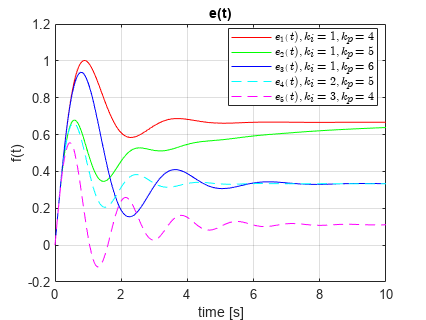


%%%    e(t)   %%%
figure;
plot(time, V* time - y_out1, 'r');
hold on;
plot(time, V* time - y_out2, 'g');
hold on;
plot(time, V* time - y_out3, 'b');
hold on;
plot(time, V* time - y_out4, 'c--');
hold on;
plot(time, V* time - y_out5, 'm--');
hold on;

title('e(t)');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('$e_1(t), k_i = 1, k_p = 4$','$e_2(t), k_i = 1, k_p = 5$','$e_3(t), k_i = 1, k_p = 6$', '$e_4(t), k_i = 2, k_p = 5$','$e_5(t), k_i = 3, k_p = 4$', 'Location', 'Best', 'Interpreter','latex');
save_file('output_task5_exp5')

## Гармонический сигнал - режим работы

simTimeStart = 0;
simTimeEnd = 50;
step = 0.002;
data.time=(simTimeStart:step:simTimeEnd)';
modelName = 'task5'; 


input = 2*sin(0.5 * data.time);
data.signals(1).values = input;
data.signals(1).dimensions = 1;

### Испытание 1,2,3 - fixed kp

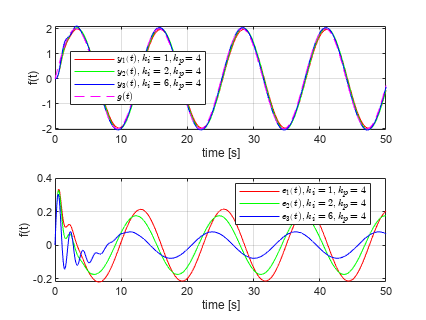

kp = 4;

load_system(modelName);
ki = 1;
out1 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
ki = 2;
out2 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
ki = 6;
out3 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out1.simout.Time;                
y_out1 = out1.simout.Data; y_out2 = out2.simout.Data; y_out3 = out3.simout.Data; 

figure;
subplot(2,1,1);
plot(time, y_out1, 'r');
hold on;
plot(time, y_out2, 'g');
hold on;
plot(time, y_out3, 'b');
hold on;
plot(time, 2*sin(0.5 * time), 'magenta--');
title(' ');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('$y_1(t), k_i = 1, k_p = 4$','$y_2(t), k_i = 2, k_p = 4$','$y_3(t), k_i = 6, k_p = 4$','$g(t)$', 'Location', 'Best', 'Interpreter','latex');

subplot(2,1,2);
plot(time, 2*sin(0.5 * time) - y_out1, 'r');
hold on;
plot(time, 2*sin(0.5 * time) - y_out2, 'g');
hold on;
plot(time, 2*sin(0.5 * time) - y_out3, 'b');
hold on;
title(' ');      
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('$e_1(t), k_i = 1, k_p = 4$','$e_2(t), k_i = 2, k_p = 4$','$e_3(t), k_i = 6, k_p = 4$', 'Location', 'Best', 'Interpreter','latex');

save_file('output_task5_exp6')

### Испытание 4, 5, 6 - fixed ki

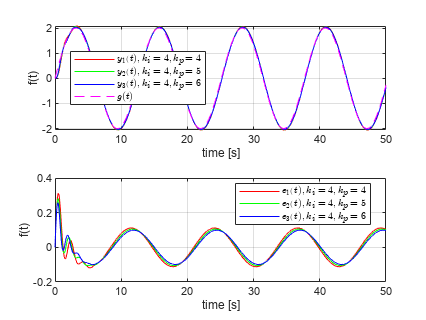

ki = 4;

load_system(modelName);
kp = 4;
out1 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
kp = 5;
out2 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
kp = 6;
out3 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out1.simout.Time;                
y_out1 = out1.simout.Data; y_out2 = out2.simout.Data; y_out3 = out3.simout.Data; 

figure;
subplot(2,1,1);
plot(time, y_out1, 'r');
hold on;
plot(time, y_out2, 'g');
hold on;
plot(time, y_out3, 'b');
hold on;
plot(time, 2*sin(0.5 * time), 'magenta--');
title(' ');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('$y_1(t), k_i = 4, k_p = 4$','$y_2(t), k_i = 4, k_p = 5$','$y_3(t), k_i = 4, k_p = 6$','$g(t)$', 'Location', 'Best', 'Interpreter','latex');

subplot(2,1,2);
plot(time, 2*sin(0.5 * time) - y_out1, 'r');
hold on;
plot(time, 2*sin(0.5 * time) - y_out2, 'g');
hold on;
plot(time, 2*sin(0.5 * time) - y_out3, 'b');
hold on;
title(' ');      
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('$e_1(t), k_i = 4, k_p = 4$','$e_2(t), k_i = 4, k_p = 5$','$e_3(t), k_i = 4, k_p = 6$', 'Location', 'Best', 'Interpreter','latex');

save_file('output_task5_exp7')

### Испытание 7, 8, 9 - дополнительные

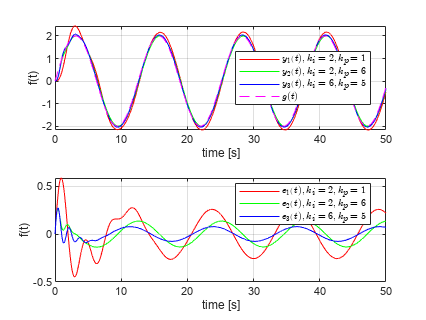

load_system(modelName);
ki = 2; kp = 1;
out1 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
ki = 2; kp = 6;
out2 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
ki = 6; kp = 5;
out3 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out1.simout.Time;                
y_out1 = out1.simout.Data; y_out2 = out2.simout.Data; y_out3 = out3.simout.Data; 

figure;
subplot(2,1,1);
plot(time, y_out1, 'r');
hold on;
plot(time, y_out2, 'g');
hold on;
plot(time, y_out3, 'b');
hold on;
plot(time, 2*sin(0.5 * time), 'magenta--');
title(' ');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('$y_1(t), k_i = 2, k_p = 1$','$y_2(t), k_i = 2, k_p = 6$','$y_3(t), k_i = 6, k_p = 5$','$g(t)$', 'Location', 'Best', 'Interpreter','latex');

subplot(2,1,2);
plot(time, 2*sin(0.5 * time) - y_out1, 'r');
hold on;
plot(time, 2*sin(0.5 * time) - y_out2, 'g');
hold on;
plot(time, 2*sin(0.5 * time) - y_out3, 'b');
hold on;
title(' ');      
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('$e_1(t), k_i = 2, k_p = 1$','$e_2(t), k_i = 2, k_p = 6$','$e_3(t), k_i = 6, k_p = 5$', 'Location', 'Best', 'Interpreter','latex');

save_file('output_task5_exp8')

### Испытания - какие-то пять штук

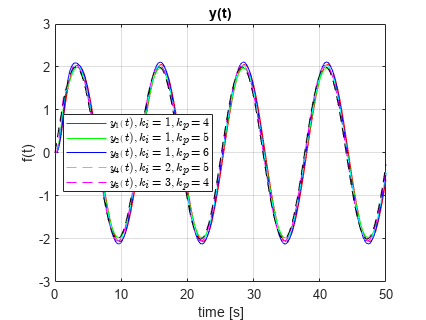

load_system(modelName);
ki = 1; kp = 2;
out1 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
ki = 1; kp = 4;
out2 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
ki = 2; kp = 2;
out3 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
ki = 2; kp = 4;
out4 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
ki = 6; kp = 5;
out5 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out1.simout.Time;                
y_out1 = out1.simout.Data; y_out2 = out2.simout.Data; y_out3 = out3.simout.Data; 
y_out4 = out4.simout.Data; y_out5 = out5.simout.Data; 

%%%    y(t)   %%%
figure;
plot(time, y_out1, 'r');
hold on;
plot(time, y_out2, 'g');
hold on;
plot(time, y_out3, 'b');
hold on;
plot(time, y_out4, 'c--');
hold on;
plot(time, y_out5, 'm--');
hold on;
plot(time, 2*sin(0.5 * time), 'black--');
title('y(t)');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('$y_1(t), k_i = 1, k_p = 4$','$y_2(t), k_i = 1, k_p = 5$','$y_3(t), k_i = 1, k_p = 6$', '$y_4(t), k_i = 2, k_p = 5$','$y_5(t), k_i = 3, k_p = 4$', 'Location', 'Best', 'Interpreter','latex');
save_file('output_task5_exp9')

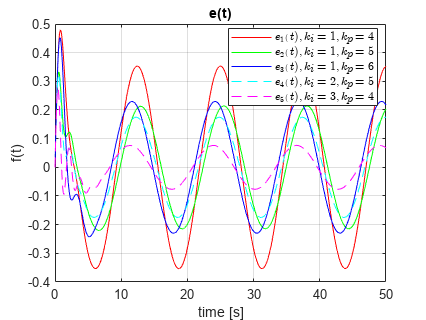


%%%    e(t)   %%%
figure;
plot(time, 2*sin(0.5 * time) - y_out1, 'r');
hold on;
plot(time, 2*sin(0.5 * time) - y_out2, 'g');
hold on;
plot(time, 2*sin(0.5 * time) - y_out3, 'b');
hold on;
plot(time, 2*sin(0.5 * time) - y_out4, 'c--');
hold on;
plot(time, 2*sin(0.5 * time) - y_out5, 'm--');
hold on;

title('e(t)');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('$e_1(t), k_i = 1, k_p = 4$','$e_2(t), k_i = 1, k_p = 5$','$e_3(t), k_i = 1, k_p = 6$', '$e_4(t), k_i = 2, k_p = 5$','$e_5(t), k_i = 3, k_p = 4$', 'Location', 'Best', 'Interpreter','latex');
save_file('output_task5_exp10')

**Функция, чтобы сохранить файл в папку**

function save_file(name)
    path = 'D:\Math\control_theory\linear_systems_labs\lab4\latex4\images';
    fullpath = fullfile(path, name);
    saveas(gcf, fullpath, 'png');

end